# Getting Started with SNOBFit

**Barnaby Walker, James H. Bannock, Adrian M. Nightingale, and John C. de Mello**

In our article, 'Tuning Reaction Products by Constrainted Optimsation', we use the algorithm Stable Noisy Optimisation by Branch and Fit (SNOBFit) by Huyer and Neumaier to carry out chemical optimisations. For convenience, we have developed a class-based wrapper for their [Matlab-based implementation of SNOBFit](http://www.mat.univie.ac.at/neum/software/snobfit/) ([http://www.mat.univie.ac.at/neum/software/snobfit/](http://www.mat.univie.ac.at/neum/software/snobfit/)), which simplifies both the installation of SNOBFit and its use, especially for chemical and blackbox optimisations. The following tutorial explains how to use this package to run an **unconstrained optimisation.**

## INSTALLATION

The code can be installed by downloading the provided zip file, extracting it, and copying the **'+snobfitclass'** folder into the folder where you want to use it. We recommend that you place it in your MATLAB directory, which is usually:

**    'C:\Users\{username}\Documents\Matlab'**

for Windows, or:

**    '~/Documents/MATLAB'**

for Mac or Linux.

Alternatively, you can get the latest version from our GitHub repository at [https://github.com/jdmgroup/snobfit-matlab-class.](https://github.com/jdmgroup/snobfit-matlab-class.) Just download (or clone) the repository into the folder you wish to use. While the latest version of the code should be stable, we encourage further development of the interface.

## RUNNING AN OPTIMISATION

To use the SNOBFit package, you first need to import it by typing the following command into the Matlab command line:

import snobfitclass.*

If you saved the SNOBFit package in the Matlab folder, you may execute this command from any folder. However, if you saved the package somewhere else, you should make sure that you are in the same folder as the package before typing the command (or alternatively you must add it to your Matlab path).

## Creating the SNOBFit Object

Our class-based wrapper is based around a 'SNOBFit optimisation object'. This object allows you to change various settings in your optimisation, run the optimisation, and save and process the data.

**The first step** in setting up an optimisation run is to create a SNOBfit object by typing:

snobfit_object = snobfitclass.snobclass()

User must enter function and setup values!


snobfit_object =   snobclass with properties:

             name: 'untitled'
              fcn: 'none'
    constraintFcn: 'none'
           linked: 0
      constrained: 0
       continuing: 0
            combo: 0
           status: []
        minimised: []
            fbest: []
            xbest: []
            ncall: 100
      termination: 'n_runs'


Here we have called our SNOBFit object "snobfit_object"  but you are free to use a different name. On entering this command, Matlab will display a list of SNOBFit object properties. Some of these can be set by the user, while others will be set during the course of the optimisation.

If you wish to see a full list of SNOBFit object properties, you can type:

snobfit_metadata = ?snobfitclass.snobclass;
snobfit_properties = reshape({snobfit_metadata.PropertyList.Name}, size(snobfit_metadata.PropertyList))

snobfit_properties = 58×1 cell array
    'uncert'
    'xcon'
    'fcon'
    'next'
    'created'
    'conStart'
    'f0'
    'Delta'
    'filepath'
    'xyMax'
    'xyMin'
    'maxRatio'
    'minRatio'
    'zMax'
    'zMin'
    'x_lower'
    'x_upper'
    'fglob'
    'xglob'
    'sigma'
    'x'
    'f'
    'F'
    'fm'
    'xVirt'
    'n'
    'ncall0'
    'dx'
    'trapezoid'
    'file'
    'nreq'
    'p'
    'npoint'
    'threshold'
    'xstart'
    'F_lower'
    'F_upper'
    'sigmaUpper'
    'sigmaLower'
    'fbestHistory'
    'ncallNoChange'
    'minCalls'
    'repeatBest'
    'plot_delay'
    'valuesToPass'
    'name'
    'fcn'
    'constraintFcn'
    'linked'
    'constrained'
    'continuing'
    'combo'
    'status'
    'minimised'
    'fbest'
    'xbest'
    'ncall'
    'termination'


**The second step** is to specify the name of the function that you want to optimise. In this example we will optimise the Branin function (a widely used test function for global optimisation), which has the functional form:


$$f\left(x_1 ,x_2 \right)={\left(x_2 -\frac{5\ldotp 1x_1^2 }{4\pi^2 }+\frac{5x_1 }{\pi }\right)}^2 +\left(10-\frac{10}{8\pi }\right)\cos \left(x_1 \right)+10\ldotp$$


Our aim is to use SNOBFit to find  the values of $x_1$ and $x_2$ that minimise the value of $f\left(x_1 ,x_2 \right)$. (Note, the Branin function has three global minima of 0.39788 at $\left(x_1 ,x_2 \right)=\left(9\ldotp 4248,2\ldotp 4750\right)\text{ }\mathrm{or}\text{ }\left(-3\ldotp 1416,12\ldotp 2750\right)\text{ }\mathrm{or}\text{ }\left(3\ldotp 1416,2\ldotp 2750\right)$, which can be readily shown by simple calculus.) 

A Matlab m-file for the Branin function can be found in the folder entitled '**+objfcn**' under the name '**bra.m**'. (The folder also contains many other widely used test functions that you may wish to try out afterwards). You can instruct SNOBFit to use '**bra.m**' as the objective function by typing: [CHANGE ILLUSTRATION TO HAVE TERMINATION AS nCall]

snobfit_object.fcn = 'bra'

SNOBFIT experiment has been created!


snobfit_object =   snobclass with properties:

             name: 'untitled'
              fcn: 'bra'
    constraintFcn: 'none'
           linked: 0
      constrained: 0
       continuing: 0
            combo: 0
           status: 'initialised'
        minimised: 0
            fbest: []
            xbest: []
            ncall: 100
      termination: 'n_runs'


Matlab will again display a list of SNOBFit object properties: notice that the "fcn" property has now been set to 'bra'.

**The third step** is to give your experiment a name by typing:

snobfit_object.name = 'my_first_snobfit'

snobfit_object =   snobclass with properties:

             name: 'my_first_snobfit'
              fcn: 'bra'
    constraintFcn: 'none'
           linked: 0
      constrained: 0
       continuing: 0
            combo: 0
           status: 'initialised'
        minimised: 0
            fbest: []
            xbest: []
            ncall: 100
      termination: 'n_runs'


The SNOBFit object uses the name you have given to save the results of your optimisation; it also uses this name to store information that it requires as it is running. If you do not specify a name it will default to 'untitled'.

You can see where your results will be saved by accessing the filepath property:

snobfit_object.filepath

ans = 'C:\Users\jdmgroup\Documents\MATLAB\SNOBFIT'

You can change the location where data will be saved by typing: snobfit_object.filepath = 'A_DIFFERENT_FILEPATH'.

**The fourth step **is to specify the maximum number of function calls to try before ending the optimisation run. By default this value is set to 100. To change it to fifty, say, you should type: 

snobfit_object.ncall = 50

snobfit_object =   snobclass with properties:

             name: 'my_first_snobfit'
              fcn: 'bra'
    constraintFcn: 'none'
           linked: 0
      constrained: 0
       continuing: 0
            combo: 0
           status: 'initialised'
        minimised: 0
            fbest: []
            xbest: []
            ncall: 50
      termination: 'n_runs'


The above steps need not be executed in order. There are also many other properties of the SNOBFit object that can be set before carrying out the optimsation. However, having carried out the above steps, we are now ready to carry out our first SNOBFit optimisation by typing:

SNOBFIT experiment is running...
Name changed to my_first_snobfit(6) to prevent naming conflict!
ncall:	1 to 6
xbest:	9.600000, 2.325000
fbest:	0.635981
ncall:	7 to 12
xbest:	9.600000, 2.325000
fbest:	0.635981
ncall:	13 to 18
xbest:	9.600000, 2.325000
fbest:	0.635981
ncall:	19 to 24
xbest:	9.600000, 2.325000
fbest:	0.635981
ncall:	25 to 30
xbest:	9.600000, 2.325000
fbest:	0.635981
ncall:	31 to 36
xbest:	9.360000, 2.700000
fbest:	0.495923
ncall:	37 to 42
xbest:	9.435000, 2.505000
fbest:	0.398845
ncall:	43 to 48
xbest:	9.435000, 2.490000
fbest:	0.398430
ncall:	49 to 54
xbest:	9.420000, 2.475000
fbest:	0.398013
SNOBFIT experiment finished after 54 function evaluations!


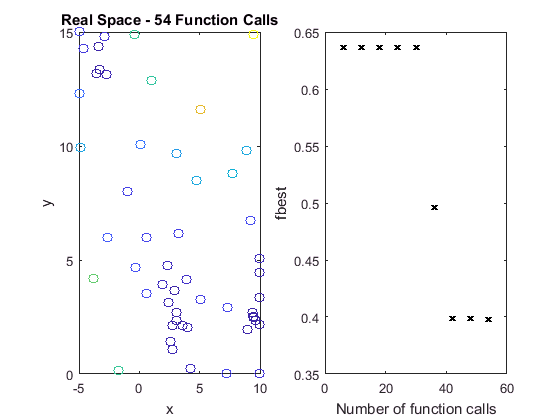

snobfit_object.startExp;

As the optimisation runs, the SNOBFit object prints out the best function value obtained so far and the corresponding input parameters. The SNOBFit object also displays two plots that show the progress of your optimisation: the left hand plot is a scatter plot of all the points tested so far. The right hand plot shows the best function value versus the number of function calls. (Due to the difficulty of plotting high dimensional data, if you are using 3 or more input parameters, the object will only plot the first two input parameters).

If you want to continue this optimisation, you can do this by typing:

snobfit_object.continuing = true;

Before starting your experiment again, you will need to increase ncall for the additional number of function evaluations you want. So if you want to run it for 50 more function evaluations, you would set ncall to 100:

snobfit_object.ncall = 100

snobfit_object =   snobclass with properties:

             name: 'my_first_snobfit(6)'
              fcn: 'bra'
    constraintFcn: 'none'
           linked: 0
      constrained: 0
       continuing: 1
            combo: 0
           status: 'complete'
        minimised: 0
            fbest: 0.3980
            xbest: [9.4200 2.4750]
            ncall: 100
      termination: 'n_runs'


Starting the experiment again will then continue your optimisation until the total number of function evaluations has been carried out again:

SNOBFIT experiment is running...
ncall:	55 to 60
xbest:	9.420000, 2.475000
fbest:	0.398013
ncall:	61 to 66
xbest:	9.420000, 2.475000
fbest:	0.398013
ncall:	67 to 72
xbest:	9.420000, 2.475000
fbest:	0.398013
ncall:	73 to 78
xbest:	9.420000, 2.475000
fbest:	0.398013
ncall:	79 to 84
xbest:	9.420000, 2.475000
fbest:	0.398013
ncall:	85 to 90
xbest:	9.420000, 2.475000
fbest:	0.398013
ncall:	91 to 96
xbest:	9.420000, 2.475000
fbest:	0.398013
ncall:	97 to 102
xbest:	9.420000, 2.475000
fbest:	0.398013
SNOBFIT experiment finished after 102 function evaluations!


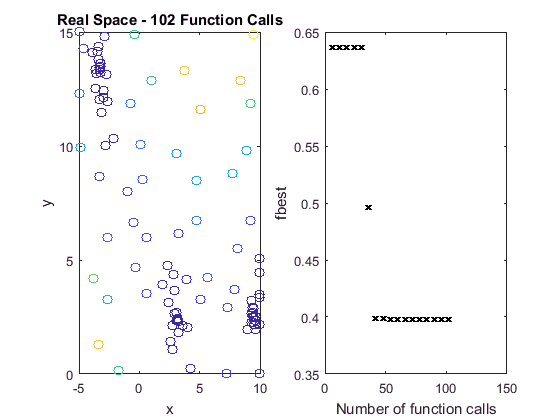

snobfit_object.startExp;

This will even work if you close MATLAB before continuing. Just create a new SNOBFit object with the same name, set continuing to true, and increase ncall as we did above.

## ACCESSING YOUR RESULTS

After your optimisation has run, you can access the results using the SNOBFit object.

The best (lowest) identified function value can be found by typing:

snobfit_object.fbest

ans = 0.3980

The location of the best point can be found by typing:

snobfit_object.xbest

ans =     9.4200    2.4750


You can also see all of the input parameters that the optimisation routine tested by typing:

snobfit_object.x

ans =     3.2400    6.1650
   -1.7100    0.1500
   -0.3150    4.6500
    9.6000    2.3250
   -0.3600   14.9100
    9.1950    6.7500
    9.4950   14.9100
   -4.8600    9.9300
    4.2450    0.2250
    5.0700   11.5950


and all of the corresponding function values by typing:

snobfit_object.f

ans =    16.1695
   88.7576
   22.6047
    0.6360
   88.2140
   20.5597
  153.5654
   58.4199
    7.4875
  120.3487


You may wish to replot the data in a different form. For instance, if you have the MATLAB Curve Fitting Toolbox installed, you may draw a contour plot based on the measured data points by typing:

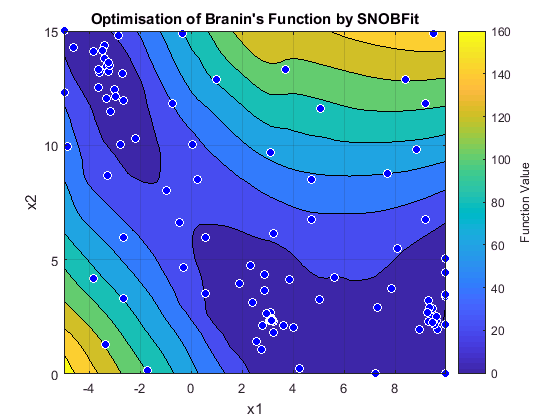

figure;
fitobject = fit(snobfit_object.x, snobfit_object.f, 'Lowess', 'Normalize', 'on');
plot(fitobject, snobfit_object.x, snobfit_object.f, 'Style', 'Contour');
c = colorbar;
xlabel('x1')
ylabel('x2')
ylabel(c, 'Function Value')
title('Optimisation of Branin''s Function by SNOBFit')

As well as storing your results inside itself, the SNOBFit object also saves a copy of itself in a '.mat' file, and the results and a summary of the optimisation results in comma-separated (.csv) files in the Results folder on the object's filepath. This means that you can load the SNOBFit object back into MATLAB from the .mat file to access the results or continue the optimisation, even if your computer turns off without you manually saving anything.